## ECE 537 : Assignment 2

Group 9 - Ashlynn Steeves, Derrell D'Souza

%close all;
%clear all;
%clc;

**Task 1** - Reload the Class A, B and C data from Exercise 1 and generated the Bayes decision boundaries for equal a priori class probabilities.

K = 1000;
D = 3;

% Dataset A
mu_A = [0 4 7];
sigma_A = [6.5000 2.1651 1.2500 ; 2.1651 5.1250 2.3816;1.2500 2.3816 2.3750];
data_A = gaussian_data(K,D,mu_A,sigma_A);

% Dataset B
mu_B = [10 5 5];
sigma_B = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456 ;-1.4481 -0.6456 1.2880];
data_B = gaussian_data(K,D,mu_B,sigma_B);

% Dataset C
mu_C = [-2 -5 -5];
sigma_C = [6.8928 -1.3750 3.1945 ;-1.3750 3.3572 0.6945;3.1945 0.6945 3.7500];
data_C = gaussian_data(K,D,mu_C,sigma_C);


Vaxis = [-15 15 -15 15 -15 15];
volume = vol3D(Vaxis, 15);

pdfA = gaus_pdf(data_A, volume); % A vector of probabilities that each point is from Class A
pdfB = gaus_pdf(data_B, volume); % A vector of probabilities that each point is from Class B
pdfC = gaus_pdf(data_C, volume); % A vector of probabilities that each point is from Class C

priors = [ 1/3 1/3 1/3]; % Apriori probabilites for each class 
classified_pts = gaus_discriminant_classifier(pdfA, pdfB, pdfC, volume, priors) % A matrix where the first three columns are respectivley an x, y and z coordinate and the fourth column is the classification of the point

classified_pts =   -15.0000  -15.0000  -15.0000    3.0000
  -15.0000  -15.0000  -12.8571    3.0000
  -15.0000  -15.0000  -10.7143    3.0000
  -15.0000  -15.0000   -8.5714    1.0000
  -15.0000  -15.0000   -6.4286    1.0000
  -15.0000  -15.0000   -4.2857    1.0000
  -15.0000  -15.0000   -2.1429    1.0000
  -15.0000  -15.0000         0    1.0000
  -15.0000  -15.0000    2.1429    1.0000
  -15.0000  -15.0000    4.2857    1.0000



classifiedA = classified_pts(classified_pts(:,4)==1,:)

classifiedA =   -15.0000  -15.0000   -8.5714    1.0000
  -15.0000  -15.0000   -6.4286    1.0000
  -15.0000  -15.0000   -4.2857    1.0000
  -15.0000  -15.0000   -2.1429    1.0000
  -15.0000  -15.0000         0    1.0000
  -15.0000  -15.0000    2.1429    1.0000
  -15.0000  -15.0000    4.2857    1.0000
  -15.0000  -15.0000    6.4286    1.0000
  -15.0000  -15.0000    8.5714    1.0000
  -15.0000  -15.0000   10.7143    1.0000


classifiedB = classified_pts(classified_pts(:,4)==2,:)

classifiedB =    -4.2857   -4.2857   15.0000    2.0000
   -4.2857   -2.1429   15.0000    2.0000
   -4.2857         0   15.0000    2.0000
   -2.1429   -4.2857   15.0000    2.0000
   -2.1429   -2.1429   15.0000    2.0000
   -2.1429         0   15.0000    2.0000
         0   -6.4286   15.0000    2.0000
         0   -4.2857   15.0000    2.0000
         0   -2.1429   12.8571    2.0000
         0   -2.1429   15.0000    2.0000


classifiedC = classified_pts(classified_pts(:,4)==3,:)

classifiedC =   -15.0000  -15.0000  -15.0000    3.0000
  -15.0000  -15.0000  -12.8571    3.0000
  -15.0000  -15.0000  -10.7143    3.0000
  -15.0000  -12.8571  -15.0000    3.0000
  -15.0000  -12.8571  -12.8571    3.0000
  -15.0000  -12.8571  -10.7143    3.0000
  -15.0000  -12.8571   -8.5714    3.0000
  -15.0000  -10.7143  -15.0000    3.0000
  -15.0000  -10.7143  -12.8571    3.0000
  -15.0000  -10.7143  -10.7143    3.0000


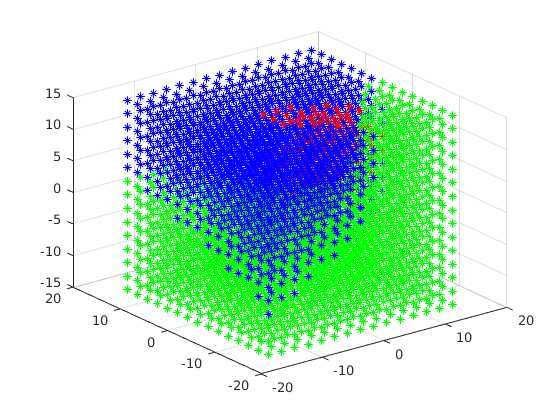


scatter3(classifiedA(:,1), classifiedA(:,2),classifiedA(:,3), '*b')
hold on;
scatter3(classifiedB(:,1), classifiedB(:,2),classifiedB(:,3), '*r')
scatter3(classifiedC(:,1), classifiedC(:,2),classifiedC(:,3), '*g')
hold off

function[classified_pts] = gaus_discriminant_classifier(pdfA,pdfB, pdfC, pts, prior)
    
    discA = log(pdfA)+log(prior(1)); % Calculate the discriminant for points belonging to Class A
    discB = log(pdfB)+log(prior(2)); % Calculate the discriminant for points belonging to Class B
    discC = log(pdfC)+log(prior(3)); % Calculate the discriminant for points belonging to Class C
    
    desc_matrix = [discA discB discC]; % Merging all discriminant values into a matrix
    [~, I] = max(desc_matrix,[], 2); % Returning the index of the largest discriminant value per row 
    % Index 1 corresponds to the point being classified as Class A, index 2
    % is Class B and index 3 is Class C.
    
    classified_pts = [pts I]; % Appending the classification of each point to the points themselves 
end 


function[pdf] = gaus_pdf(class ,pts)
    mu = mean(class); % Calculating the mean of the given class
    
    sigma = cov(class); % Calculating the covarriance of the given class
    sigma_inv = inv(sigma); % Calculating the inverse of the covarriance
    
    d = length(mu); % Determining the dimensionality of the data
    
    xmmu = pts-mu; % Subtracting the mean from each point in the dataset
    norm = (1/((2*pi)^(d/2)))*(det(sigma)^(-1/2)); % Calculating the normalization constant (from the multivarriate gaussian eq)
    exp_term = zeros(length(xmmu),1); % Initializing the vector of exponential terms 
    
    for i = 1:length(xmmu)
        exp_term(i) = -1/2*xmmu(i,:)*sigma_inv*xmmu(i,:)'; % Calculating the term that will be in the exponent (from the multivarriate gaussian eq) for each datapoint
    end
    
    pdf = norm*exp(exp_term); % Combining terms to generate the probability that a point is from the given class
end


function f = gaussian_data(K,D,mu,sigma)
    N = randn(K,D); % Generate a subset of K D-dimensional samples from a normal distribution
    N_c = N - mean(N); % Centralize the data at zero-mean
    
    [v,d] = eig(cov(N_c)); % Obtain eigen values and eigen vectors for covariance of N    
    R = v*inv(sqrt(d)); % Generate the whitening transform
    W  = N_c*R; % Apply the whitening transform on the centralized data
    
    [vn,dn] = eig(sigma); % Obtain eigen values and eigen vectors of the desired covariance
    R_inv = sqrt(dn)*inv(vn); % Generate the inverse whitening transform
    f = W*R_inv; % Apply the inverse whitening transfrom on the whitened gaussian data 
    f = f + mu; % Centralize the data at the desired mu
end 

function V = vol3D(Vaxis,Num)

NV = Num;

if length(Vaxis) == 2
    Vaxis = [Vaxis Vaxis Vaxis];
end

min_a = Vaxis(1);
max_a = Vaxis(2);
res = (max_a-min_a)/(NV-1);

r = min_a:res:max_a;
r = r(:);

rx = [Vaxis(1):(Vaxis(2)-Vaxis(1))/(NV-1):Vaxis(2)]';
ry = [Vaxis(3):(Vaxis(4)-Vaxis(3))/(NV-1):Vaxis(4)]';
rz = [Vaxis(5):(Vaxis(6)-Vaxis(5))/(NV-1):Vaxis(6)]';

x = zeros(3,length(rz)^3);
k =1;
j = 1;
for i = 1:length(rz):length(x)
    x(3,(i-1)+(1:length(rz)))= rz;
    x(2,(i-1)+(1:length(rz))) = ry(k)*ones(1,length(rz));
    x(1,(i-1)+(1:length(rz))) = rx(j)*ones(1,length(rz));
    k = k+1;
    if k > length(rz)
        k =1;
        j = j +1;
    end
end
x = x';
V = x;

end